# Irminger 7 CTD Casts

First produces a rough map of the CTD casts from Irminger 7 in the vicinity of OOI assets. Each CTD cast is then plotted for temperature, salinity, and dissolved oxygen. 

Kristen Fogaren 12/3/2020

- Data was downloaded from Alfresco

- Data conversion with Seabird Software

- Processed casts in Python and output to CSV

- Read into Matab as tables

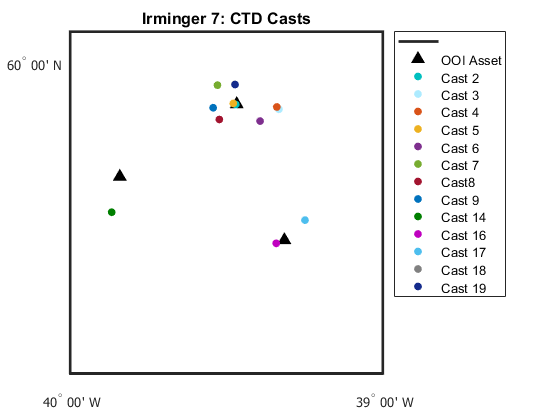

% Set up workspace 
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\My Drive\Matlab_work\BC\IrmingerData\Year7')
load Irm7_CTD_Casts.mat

% OOI asset locations 
ooi_latlon = [59.9341, -39.4673
    59.8177, -39.8412
    59.7155, -39.3148];
    
% Setup the Map Axes
figure
axesm('MapProjection','mercator'); 
minlat=min(ooi_latlon(:,1)); maxlat=max(ooi_latlon(:,1)); 
minlon=min(ooi_latlon(:,2)); maxlon=max(ooi_latlon(:,1)); 

% New Lat/Lon Limits
ll = [-40 59.5; -39 60.05];

setm(gca, 'MapLatLimit',[ll(1,2) ll(2,2)],...
          'MapLonLimit',[ll(1,1) ll(2,1)]);
setm(gca,'MLineLocation',1,'MLabelLocation',1,...
    'MeridianLabel','on','MLabelParallel','south'); 
setm(gca,'PLineLocation',1,'PLabelLocation',1,...
    'ParallelLabel','on','PLabelMeridian','west');
tightmap;
setm(gca,'FontWeight','normal','FontSize',10,'FontName','Tahoma','LabelUnits','dm'); 

% Add lat/lon tickmarks for every degree if the map spans 
% greater than 1.5 degrees longitude, or every quarter degree if less.
if abs(maxlon-minlon)>1.5
  setm(gca,'MLineLocation',1,'MLabelLocation',1,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',1,'PLabelLocation',1,'ParallelLabel','on','PLabelMeridian','west');
else
  setm(gca,'MLineLocation',0.25,'MLabelLocation',0.25,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',0.25,'PLabelLocation',0.25,'ParallelLabel','on','PLabelMeridian','west');
end

% Plot Casts/OOI Assets
plotm(ooi_latlon(:,1),ooi_latlon(:,2),'^','markersize',8,'MarkerFaceColor','k',...
    'MarkerEdgeColor','k')
hold on
plotm(nanmean(ar46002down.latitude),nanmean(ar46002down.longitude),'.','markersize',20,'Color',teal)
plotm(nanmean(ar46003down.latitude),nanmean(ar46003down.longitude),'.','markersize',20,'Color',lightcyan)
plotm(nanmean(ar46004down.latitude),nanmean(ar46004down.longitude),'.','markersize',20,'Color',red)
plotm(nanmean(ar46005down.latitude),nanmean(ar46005down.longitude),'.','markersize',20,'Color',yellow)
plotm(nanmean(ar46006down.latitude),nanmean(ar46006down.longitude),'.','markersize',20,'Color',purple)
plotm(nanmean(ar46007down.latitude),nanmean(ar46007down.longitude),'.','markersize',20,'Color',green)
plotm(nanmean(ar46008down.latitude),nanmean(ar46008down.longitude),'.','markersize',20,'Color',maroon)
plotm(nanmean(ar46009down.latitude),nanmean(ar46009down.longitude),'.','markersize',20,'Color',blue)
% plotm(nanmean(ar46010down.latitude),nanmean(ar46010down.longitude),'.','markersize',20,'Color',forestgreen)
% plotm(nanmean(ar46011down.latitude),nanmean(ar46011down.longitude),'.','markersize',20,'Color',grey)
% plotm(nanmean(ar46012down.latitude),nanmean(ar46012down.longitude),'.','markersize',20,'Color',brightpurple)
% plotm(nanmean(ar46013down.latitude),nanmean(ar46013down.longitude),'.','markersize',20,'Color',cyan)
plotm(nanmean(ar46014down.latitude),nanmean(ar46014down.longitude),'.','markersize',20,'Color',forestgreen)
%plotm(nanmean(ar46015down.latitude),nanmean(ar46015down.longitude),'.','markersize',20,'Color',grey)
plotm(nanmean(ar46016down.latitude),nanmean(ar46016down.longitude),'.','markersize',20,'Color',brightpurple)
plotm(nanmean(ar46017down.latitude),nanmean(ar46017down.longitude),'.','markersize',20,'Color',cyan)
plotm(nanmean(ar46018down.latitude),nanmean(ar46018down.longitude),'.','markersize',20,'Color',grey)
plotm(nanmean(ar46019down.latitude),nanmean(ar46019down.longitude),'.','markersize',20,'Color',navy)
title('Irminger 7: CTD Casts')
legend('','OOI Asset','Cast 2','Cast 3','Cast 4','Cast 5','Cast 6','Cast 7','Cast8','Cast 9',...
    'Cast 14','Cast 16','Cast 17','Cast 18','Cast 19','Location','bestoutside')

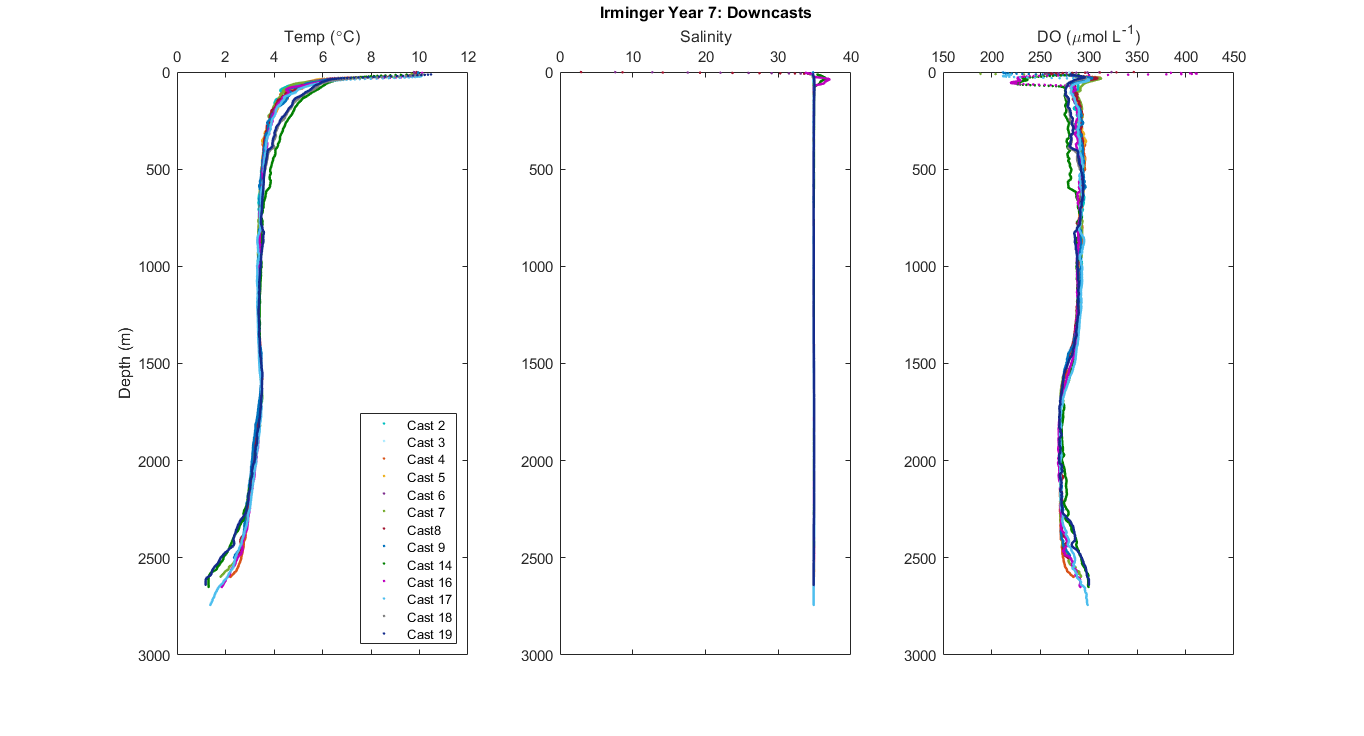

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46002down.t090C,ar46002down.depSM,'.','Color',teal)
hold on
plot(ar46003down.t090C,ar46003down.depSM,'.','Color',lightcyan)
plot(ar46004down.t090C,ar46004down.depSM,'.','Color',red)
plot(ar46005down.t090C,ar46005down.depSM,'.','Color',yellow)
plot(ar46006down.t090C,ar46006down.depSM,'.','Color',purple)
plot(ar46007down.t090C,ar46007down.depSM,'.','Color',green)
plot(ar46008down.t090C,ar46008down.depSM,'.','Color',maroon)
plot(ar46009down.t090C,ar46009down.depSM,'.','Color',blue)
plot(ar46014down.t090C,ar46014down.depSM,'.','Color',forestgreen)
plot(ar46016down.t090C,ar46016down.depSM,'.','Color',brightpurple)
plot(ar46017down.t090C,ar46017down.depSM,'.','Color',cyan)
plot(ar46018down.t090C,ar46018down.depSM,'.','Color',grey)
plot(ar46019down.t090C,ar46019down.depSM,'.','Color',navy)
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 2','Cast 3','Cast 4','Cast 5','Cast 6','Cast 7','Cast8','Cast 9',...
    'Cast 14','Cast 16','Cast 17','Cast 18','Cast 19','Location','SE')

s2 = subplot(1,3,2);
plot(ar46002down.sal00,ar46002down.depSM,'.','Color',teal)
hold on
plot(ar46003down.sal00,ar46003down.depSM,'.','Color',lightcyan)
plot(ar46004down.sal00,ar46004down.depSM,'.','Color',red)
plot(ar46005down.sal00,ar46005down.depSM,'.','Color',yellow)
plot(ar46006down.sal00,ar46006down.depSM,'.','Color',purple)
plot(ar46007down.sal00,ar46007down.depSM,'.','Color',green)
plot(ar46008down.sal00,ar46008down.depSM,'.','Color',maroon)
plot(ar46009down.sal00,ar46009down.depSM,'.','Color',blue)
plot(ar46014down.sal00,ar46014down.depSM,'.','Color',forestgreen)
plot(ar46016down.sal00,ar46016down.depSM,'.','Color',brightpurple)
plot(ar46017down.sal00,ar46017down.depSM,'.','Color',cyan)
plot(ar46018down.sal00,ar46018down.depSM,'.','Color',grey)
plot(ar46019down.sal00,ar46019down.depSM,'.','Color',navy)
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Downcasts')

s3 = subplot(1,3,3);
plot(ar46002down.sbeox0MLL*44.661,ar46002down.depSM,'.','Color',teal)
hold on
plot(ar46003down.sbeox0MLL*44.661,ar46003down.depSM,'.','Color',lightcyan)
plot(ar46004down.sbeox0MLL*44.661,ar46004down.depSM,'.','Color',red)
plot(ar46005down.sbeox0MLL*44.661,ar46005down.depSM,'.','Color',yellow)
plot(ar46006down.sbeox0MLL*44.661,ar46006down.depSM,'.','Color',purple)
plot(ar46007down.sbeox0MLL*44.661,ar46007down.depSM,'.','Color',green)
plot(ar46008down.sbeox0MLL*44.661,ar46008down.depSM,'.','Color',maroon)
plot(ar46009down.sbeox0MLL*44.661,ar46009down.depSM,'.','Color',blue)
plot(ar46014down.sbeox0MLL*44.661,ar46014down.depSM,'.','Color',forestgreen)
plot(ar46016down.sbeox0MLL*44.661,ar46016down.depSM,'.','Color',brightpurple)
plot(ar46017down.sbeox0MLL*44.661,ar46017down.depSM,'.','Color',cyan)
plot(ar46018down.sbeox0MLL*44.661,ar46018down.depSM,'.','Color',grey)
plot(ar46019down.sbeox0MLL*44.661,ar46019down.depSM,'.','Color',navy)
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

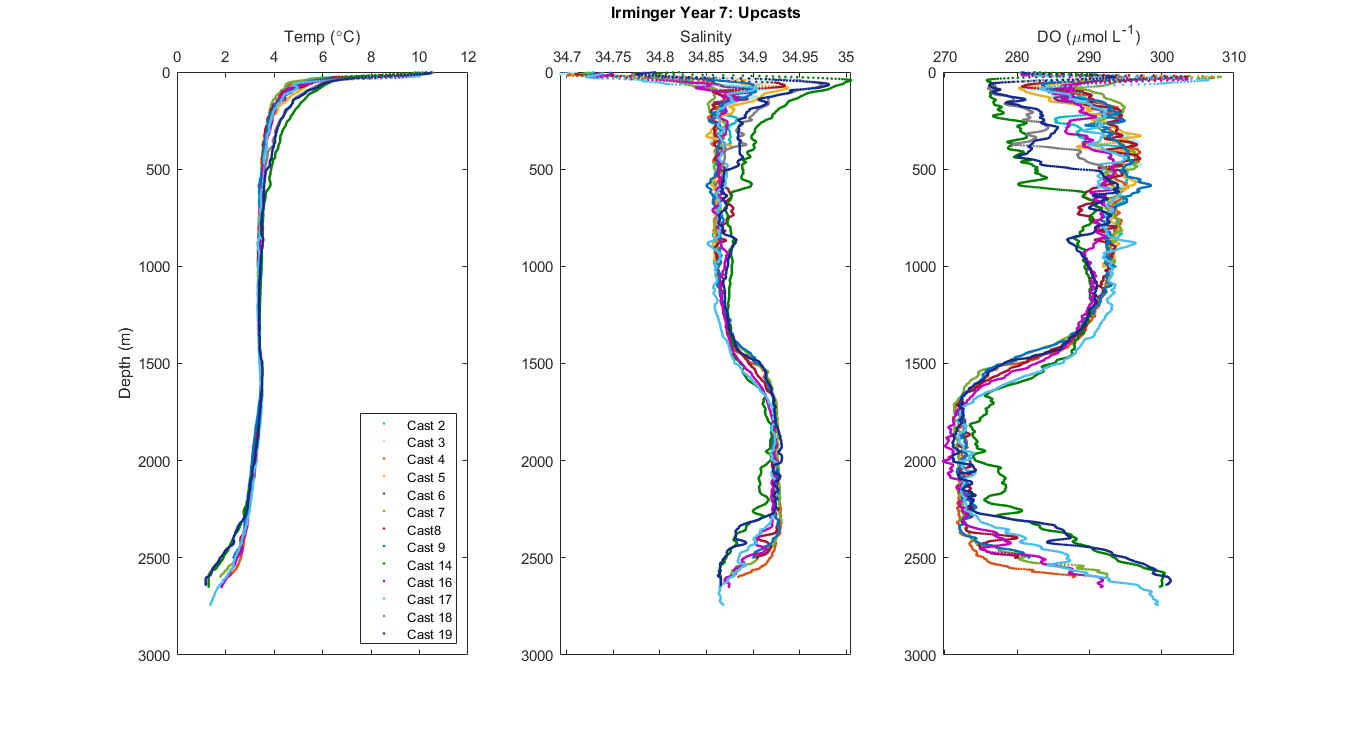

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46002up.t090C,ar46002up.depSM,'.','Color',teal)
hold on
plot(ar46003up.t090C,ar46003up.depSM,'.','Color',lightcyan)
plot(ar46004up.t090C,ar46004up.depSM,'.','Color',red)
plot(ar46005up.t090C,ar46005up.depSM,'.','Color',yellow)
plot(ar46006up.t090C,ar46006up.depSM,'.','Color',purple)
plot(ar46007up.t090C,ar46007up.depSM,'.','Color',green)
plot(ar46008up.t090C,ar46008up.depSM,'.','Color',maroon)
plot(ar46009up.t090C,ar46009up.depSM,'.','Color',blue)
plot(ar46014up.t090C,ar46014up.depSM,'.','Color',forestgreen)
plot(ar46016up.t090C,ar46016up.depSM,'.','Color',brightpurple)
plot(ar46017up.t090C,ar46017up.depSM,'.','Color',cyan)
plot(ar46018up.t090C,ar46018up.depSM,'.','Color',grey)
plot(ar46019up.t090C,ar46019up.depSM,'.','Color',navy)
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 2','Cast 3','Cast 4','Cast 5','Cast 6','Cast 7','Cast8','Cast 9',...
    'Cast 14','Cast 16','Cast 17','Cast 18','Cast 19','Location','SE')

s2 = subplot(1,3,2);
plot(ar46002up.sal00,ar46002up.depSM,'.','Color',teal)
hold on
plot(ar46003up.sal00,ar46003up.depSM,'.','Color',lightcyan)
plot(ar46004up.sal00,ar46004up.depSM,'.','Color',red)
plot(ar46005up.sal00,ar46005up.depSM,'.','Color',yellow)
plot(ar46006up.sal00,ar46006up.depSM,'.','Color',purple)
plot(ar46007up.sal00,ar46007up.depSM,'.','Color',green)
plot(ar46008up.sal00,ar46008up.depSM,'.','Color',maroon)
plot(ar46009up.sal00,ar46009up.depSM,'.','Color',blue)
plot(ar46014up.sal00,ar46014up.depSM,'.','Color',forestgreen)
plot(ar46016up.sal00,ar46016up.depSM,'.','Color',brightpurple)
plot(ar46017up.sal00,ar46017up.depSM,'.','Color',cyan)
plot(ar46018up.sal00,ar46018up.depSM,'.','Color',grey)
plot(ar46019up.sal00,ar46019up.depSM,'.','Color',navy)
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Upcasts')

s3 = subplot(1,3,3);
plot(ar46002up.sbeox0MLL*44.661,ar46002up.depSM,'.','Color',teal)
hold on
plot(ar46003up.sbeox0MLL*44.661,ar46003up.depSM,'.','Color',lightcyan)
plot(ar46004up.sbeox0MLL*44.661,ar46004up.depSM,'.','Color',red)
plot(ar46005up.sbeox0MLL*44.661,ar46005up.depSM,'.','Color',yellow)
plot(ar46006up.sbeox0MLL*44.661,ar46006up.depSM,'.','Color',purple)
plot(ar46007up.sbeox0MLL*44.661,ar46007up.depSM,'.','Color',green)
plot(ar46008up.sbeox0MLL*44.661,ar46008up.depSM,'.','Color',maroon)
plot(ar46009up.sbeox0MLL*44.661,ar46009up.depSM,'.','Color',blue)
plot(ar46014up.sbeox0MLL*44.661,ar46014up.depSM,'.','Color',forestgreen)
plot(ar46016up.sbeox0MLL*44.661,ar46016up.depSM,'.','Color',brightpurple)
plot(ar46017up.sbeox0MLL*44.661,ar46017up.depSM,'.','Color',cyan)
plot(ar46018up.sbeox0MLL*44.661,ar46018up.depSM,'.','Color',grey)
plot(ar46019up.sbeox0MLL*44.661,ar46019up.depSM,'.','Color',navy)
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

- Colors in CTD plots correspond to location colors in the map above. 

## Upcasts versus Downcasts 

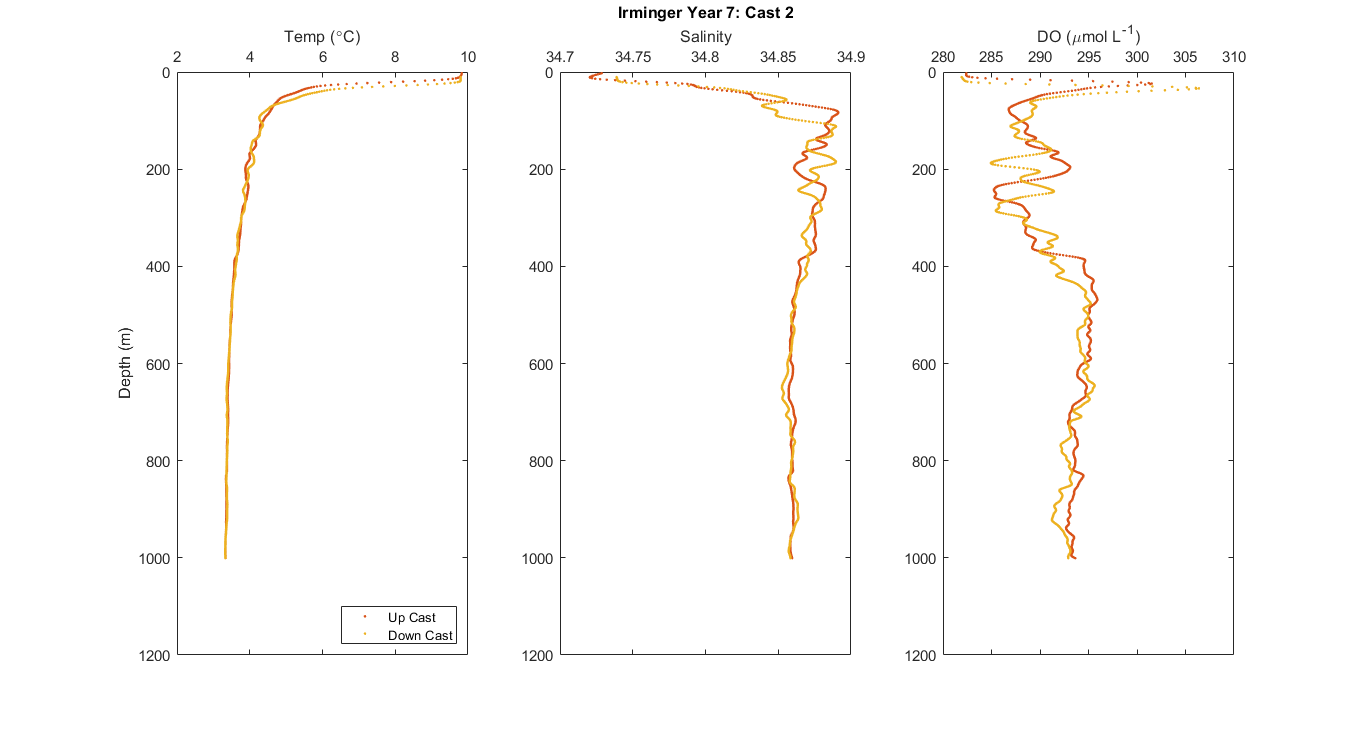

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46002up.t090C,ar46002up.depSM,'.','Color',red);
hold on
plot(ar46002down.t090C,ar46002down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46002up.sal00,ar46002up.depSM,'.','Color',red);
hold on
plot(ar46002down.sal00,ar46002down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 2')

s3 = subplot(1,3,3);
plot(ar46002up.sbeox0MLL*44.661,ar46002up.depSM,'.','Color',red);
hold on
plot(ar46002down.sbeox0MLL*44.661,ar46002down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

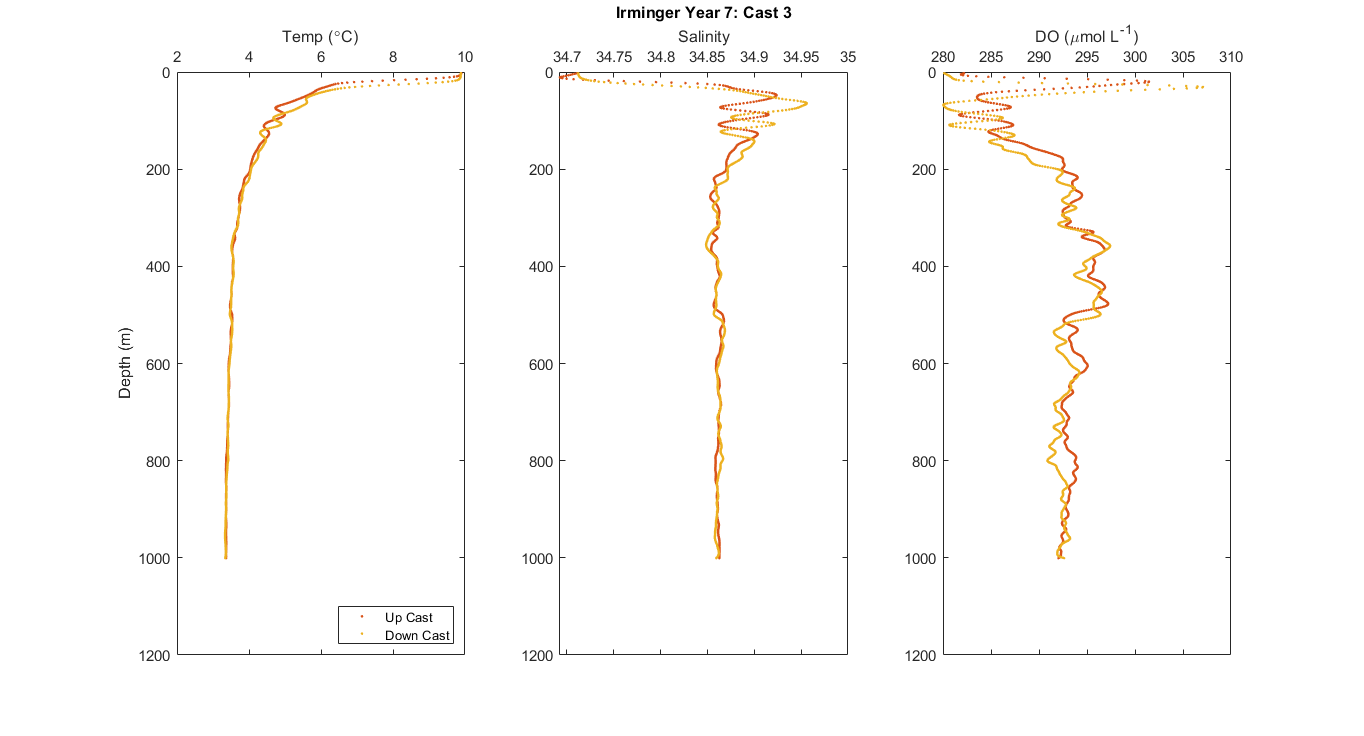



f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46003up.t090C,ar46003up.depSM,'.','Color',red);
hold on
plot(ar46003down.t090C,ar46003down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46003up.sal00,ar46003up.depSM,'.','Color',red);
hold on
plot(ar46003down.sal00,ar46003down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 3')

s3 = subplot(1,3,3);
plot(ar46003up.sbeox0MLL*44.661,ar46003up.depSM,'.','Color',red);
hold on
plot(ar46003down.sbeox0MLL*44.661,ar46003down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

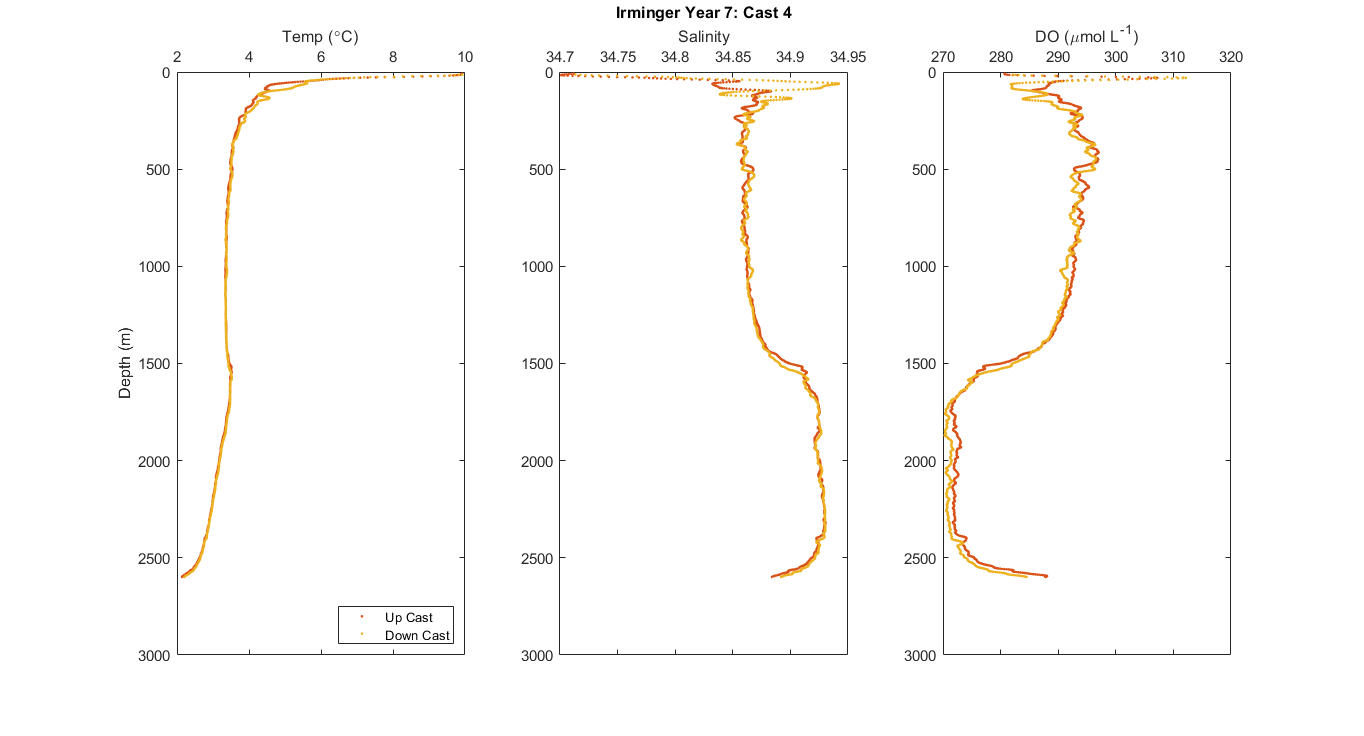



f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46004up.t090C,ar46004up.depSM,'.','Color',red);
hold on
plot(ar46004down.t090C,ar46004down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46004up.sal00,ar46004up.depSM,'.','Color',red);
hold on
plot(ar46004down.sal00,ar46004down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 4')

s3 = subplot(1,3,3);
plot(ar46004up.sbeox0MLL*44.661,ar46004up.depSM,'.','Color',red);
hold on
plot(ar46004down.sbeox0MLL*44.661,ar46004down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

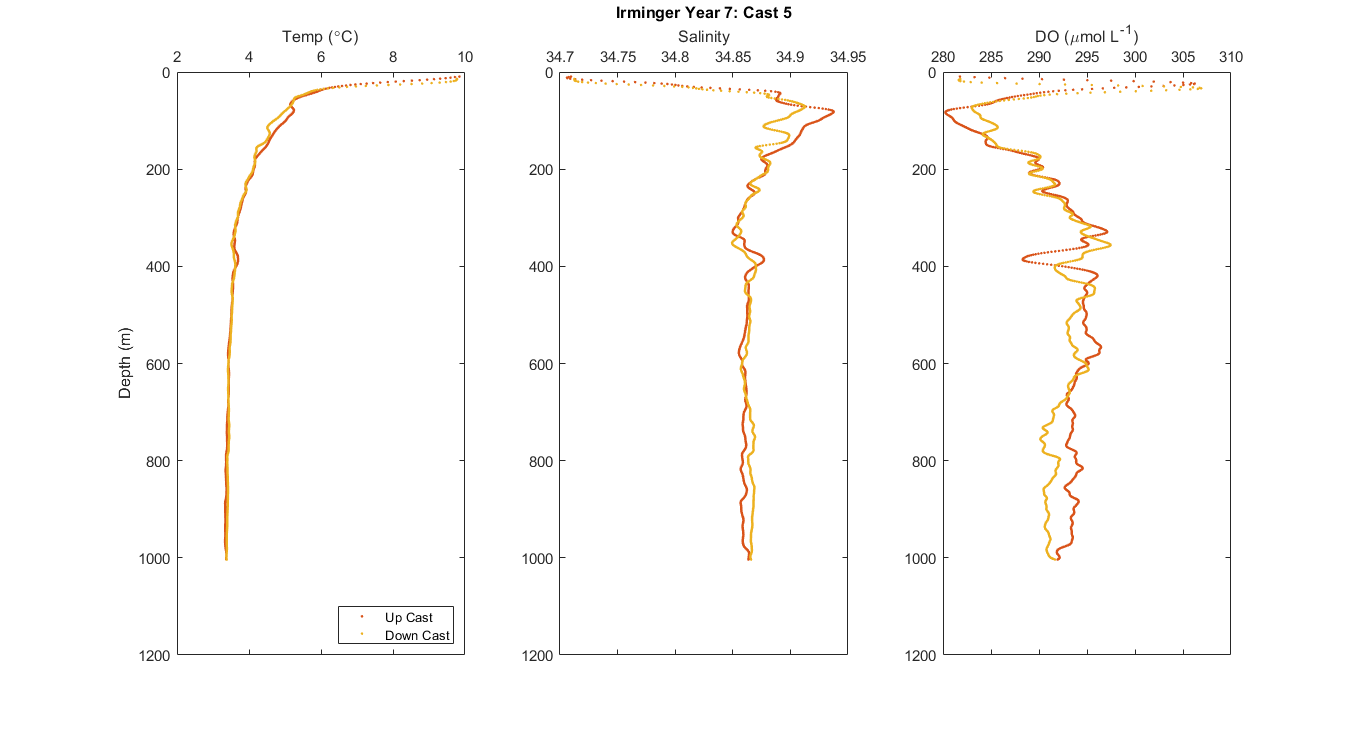

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46005up.t090C,ar46005up.depSM,'.','Color',red);
hold on
plot(ar46005down.t090C,ar46005down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46005up.sal00,ar46005up.depSM,'.','Color',red);
hold on
plot(ar46005down.sal00,ar46005down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 5')

s3 = subplot(1,3,3);
plot(ar46005up.sbeox0MLL*44.661,ar46005up.depSM,'.','Color',red);
hold on
plot(ar46005down.sbeox0MLL*44.661,ar46005down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

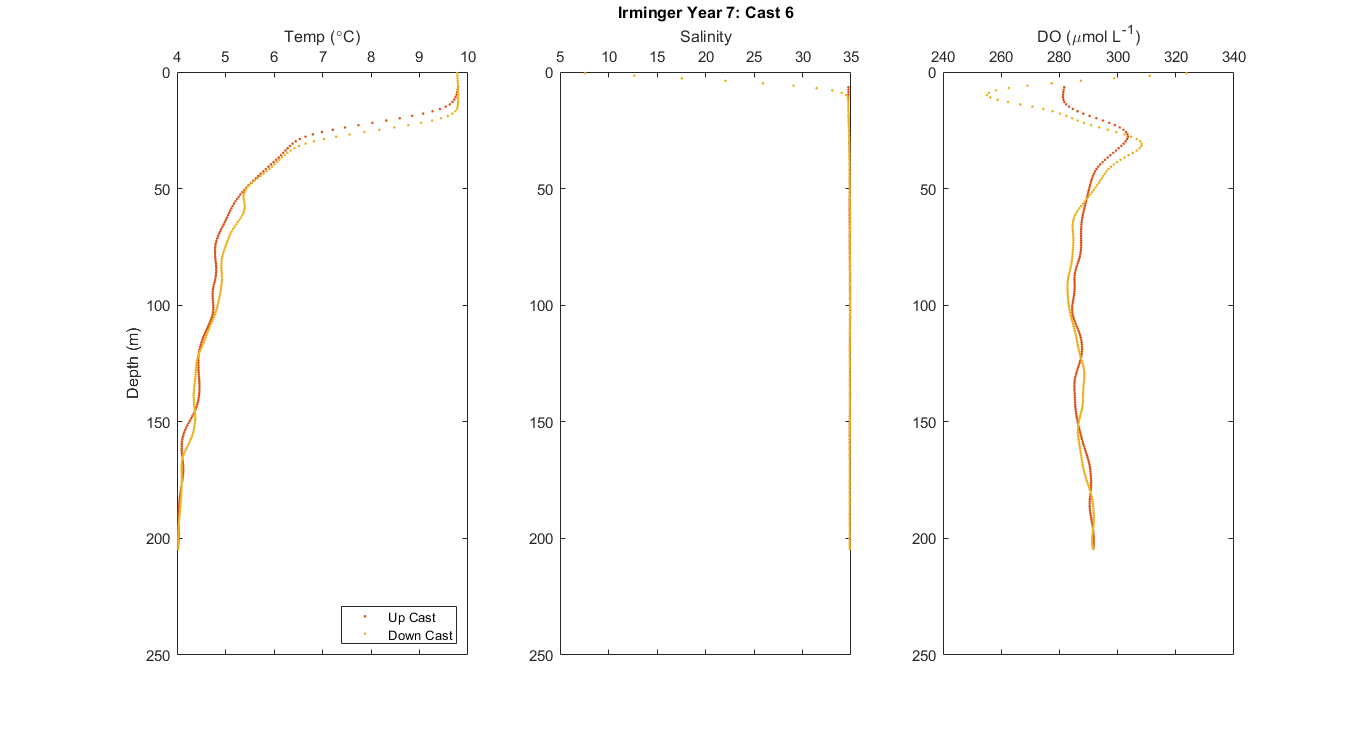

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46006up.t090C,ar46006up.depSM,'.','Color',red);
hold on
plot(ar46006down.t090C,ar46006down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46006up.sal00,ar46006up.depSM,'.','Color',red);
hold on
plot(ar46006down.sal00,ar46006down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 6')

s3 = subplot(1,3,3);
plot(ar46006up.sbeox0MLL*44.661,ar46006up.depSM,'.','Color',red);
hold on
plot(ar46006down.sbeox0MLL*44.661,ar46006down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

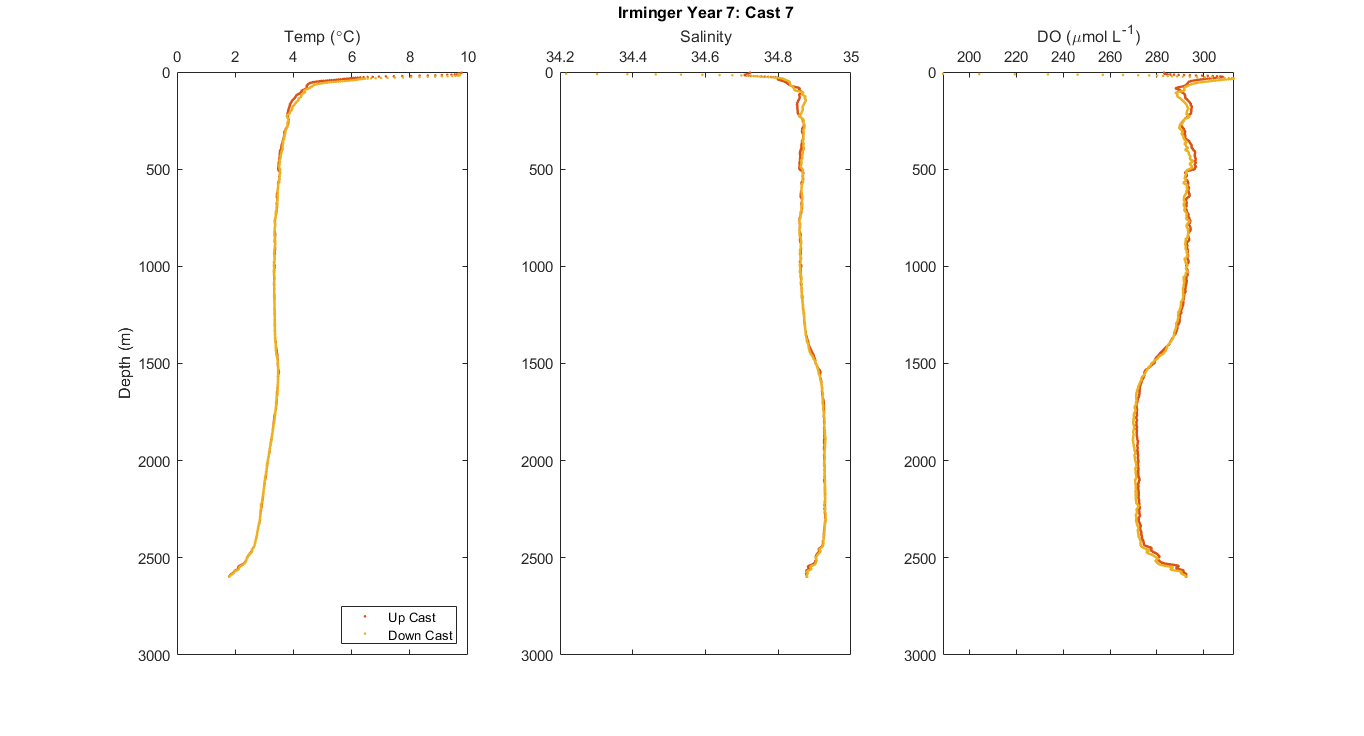

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46007up.t090C,ar46007up.depSM,'.','Color',red);
hold on
plot(ar46007down.t090C,ar46007down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46007up.sal00,ar46007up.depSM,'.','Color',red);
hold on
plot(ar46007down.sal00,ar46007down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 7')

s3 = subplot(1,3,3);
plot(ar46007up.sbeox0MLL*44.661,ar46007up.depSM,'.','Color',red);
hold on
plot(ar46007down.sbeox0MLL*44.661,ar46007down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

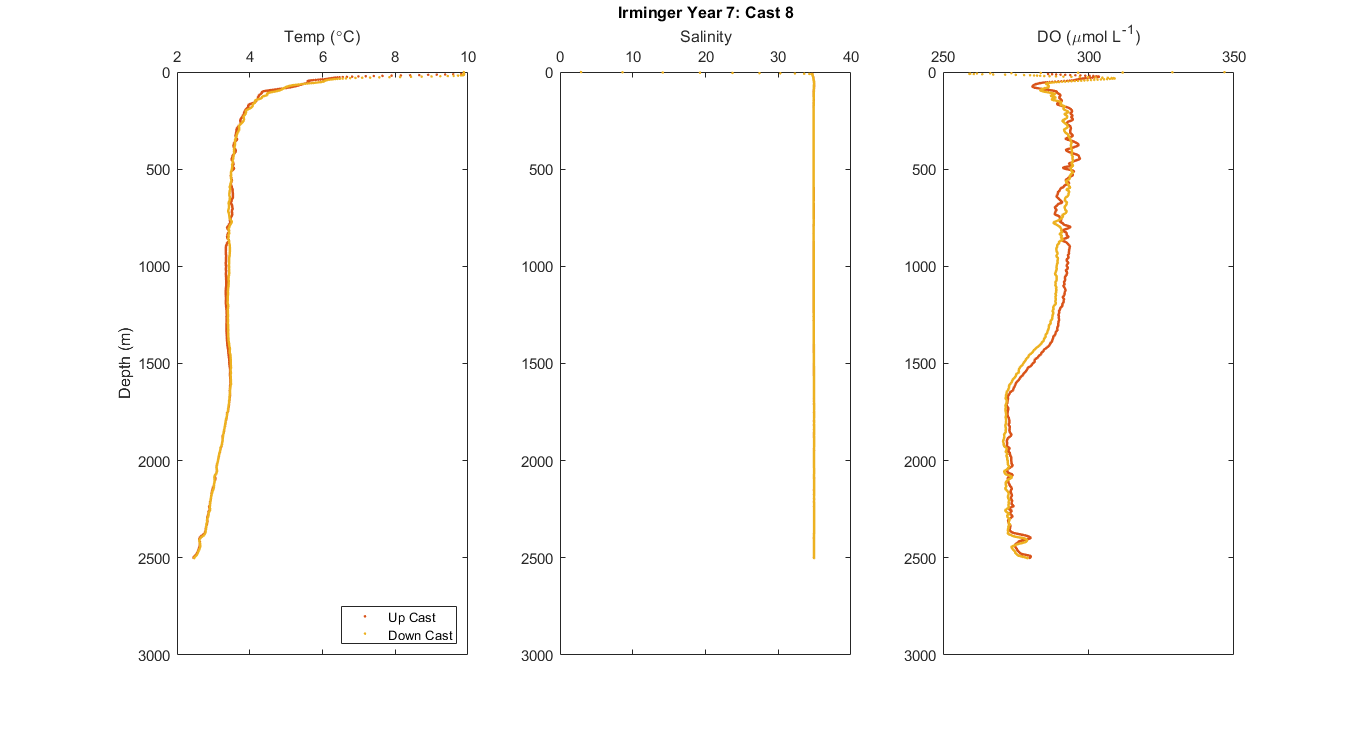

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46008up.t090C,ar46008up.depSM,'.','Color',red);
hold on
plot(ar46008down.t090C,ar46008down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46008up.sal00,ar46008up.depSM,'.','Color',red);
hold on
plot(ar46008down.sal00,ar46008down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 8')

s3 = subplot(1,3,3);
plot(ar46008up.sbeox0MLL*44.661,ar46008up.depSM,'.','Color',red);
hold on
plot(ar46008down.sbeox0MLL*44.661,ar46008down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

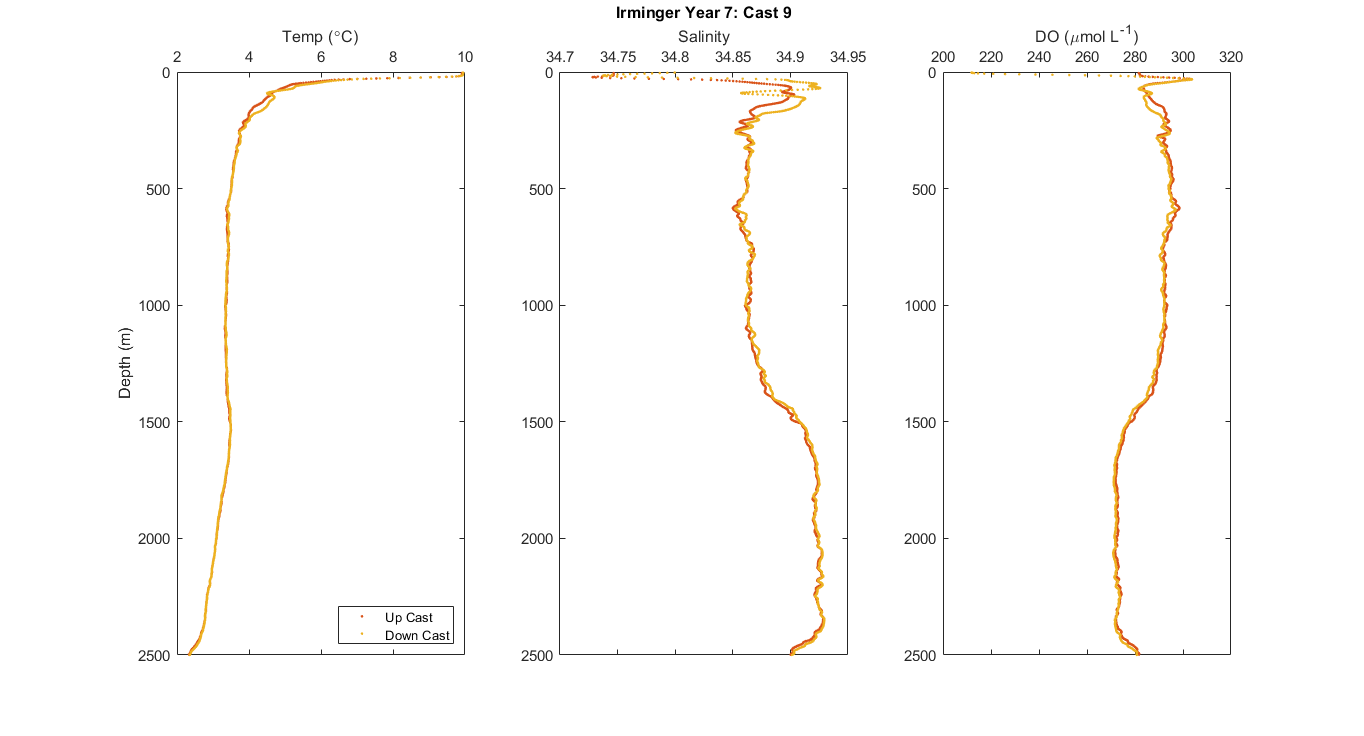


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46009up.t090C,ar46009up.depSM,'.','Color',red);
hold on
plot(ar46009down.t090C,ar46009down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46009up.sal00,ar46009up.depSM,'.','Color',red);
hold on
plot(ar46009down.sal00,ar46009down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 9')

s3 = subplot(1,3,3);
plot(ar46009up.sbeox0MLL*44.661,ar46009up.depSM,'.','Color',red);
hold on
plot(ar46009down.sbeox0MLL*44.661,ar46009down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

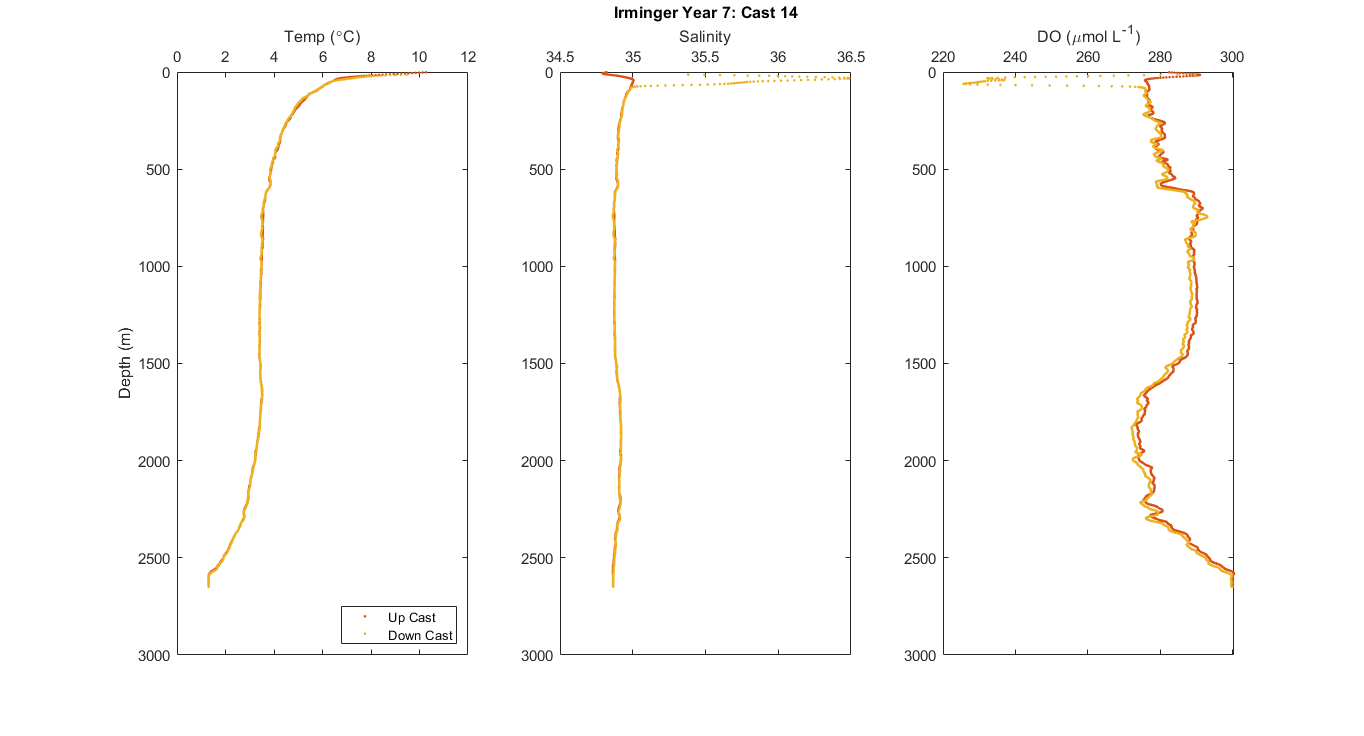

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46014up.t090C,ar46014up.depSM,'.','Color',red);
hold on
plot(ar46014down.t090C,ar46014down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46014up.sal00,ar46014up.depSM,'.','Color',red);
hold on
plot(ar46014down.sal00,ar46014down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 14')

s3 = subplot(1,3,3);
plot(ar46014up.sbeox0MLL*44.661,ar46014up.depSM,'.','Color',red);
hold on
plot(ar46014down.sbeox0MLL*44.661,ar46014down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

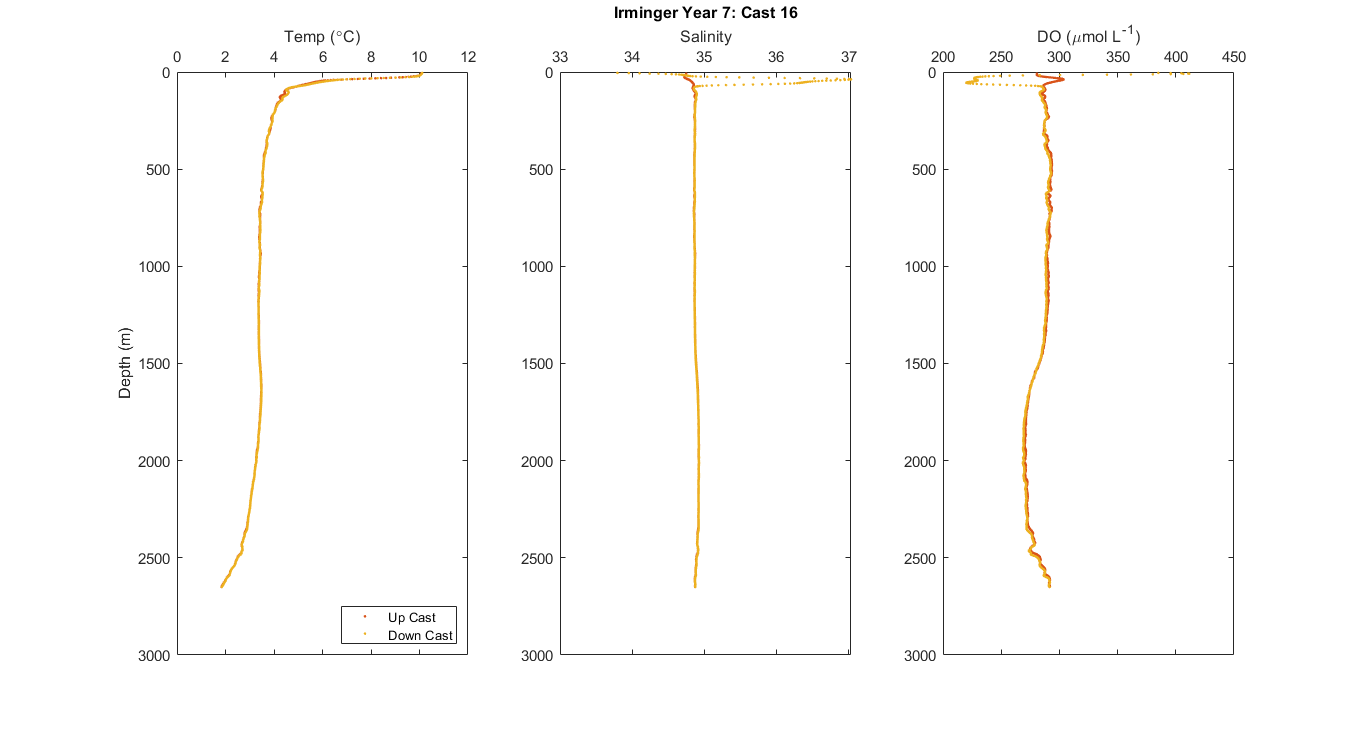


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46016up.t090C,ar46016up.depSM,'.','Color',red);
hold on
plot(ar46016down.t090C,ar46016down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46016up.sal00,ar46016up.depSM,'.','Color',red);
hold on
plot(ar46016down.sal00,ar46016down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 16')

s3 = subplot(1,3,3);
plot(ar46016up.sbeox0MLL*44.661,ar46016up.depSM,'.','Color',red);
hold on
plot(ar46016down.sbeox0MLL*44.661,ar46016down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

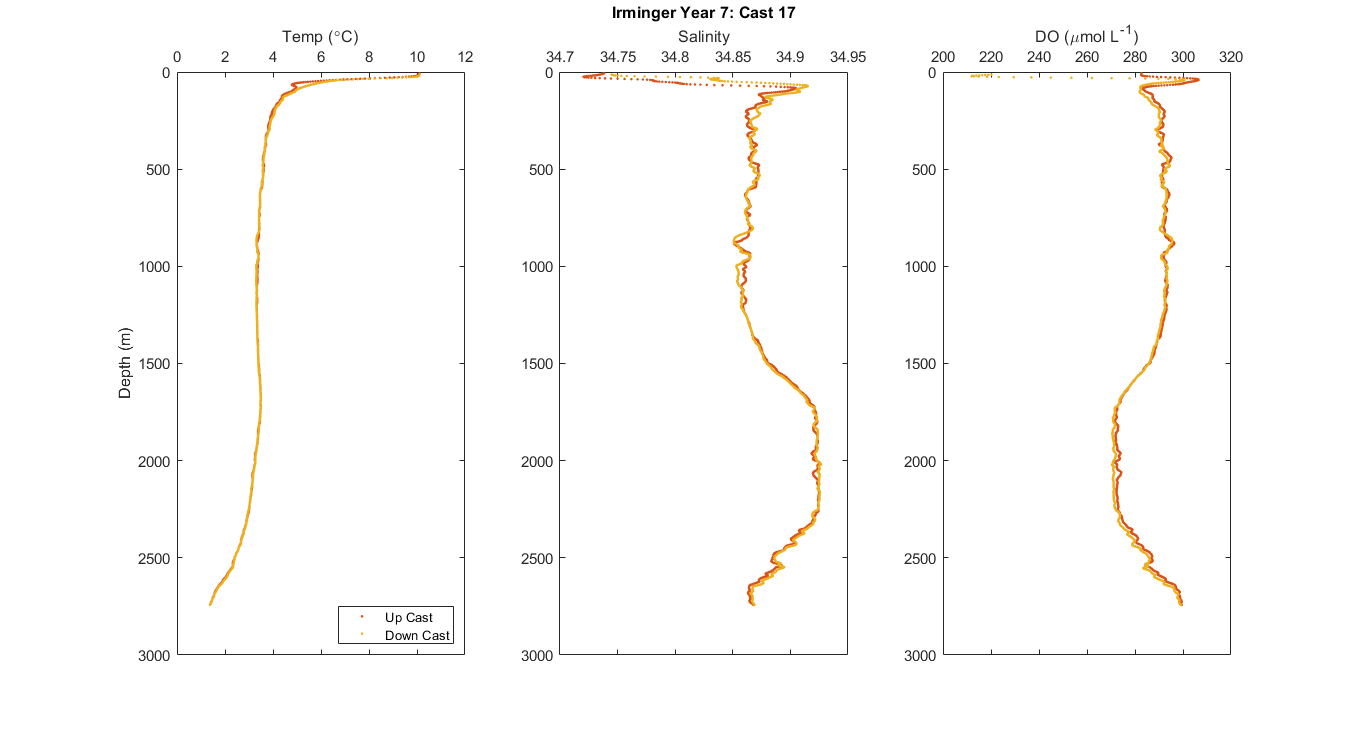




f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46017up.t090C,ar46017up.depSM,'.','Color',red);
hold on
plot(ar46017down.t090C,ar46017down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46017up.sal00,ar46017up.depSM,'.','Color',red);
hold on
plot(ar46017down.sal00,ar46017down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 17')

s3 = subplot(1,3,3);
plot(ar46017up.sbeox0MLL*44.661,ar46017up.depSM,'.','Color',red);
hold on
plot(ar46017down.sbeox0MLL*44.661,ar46017down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

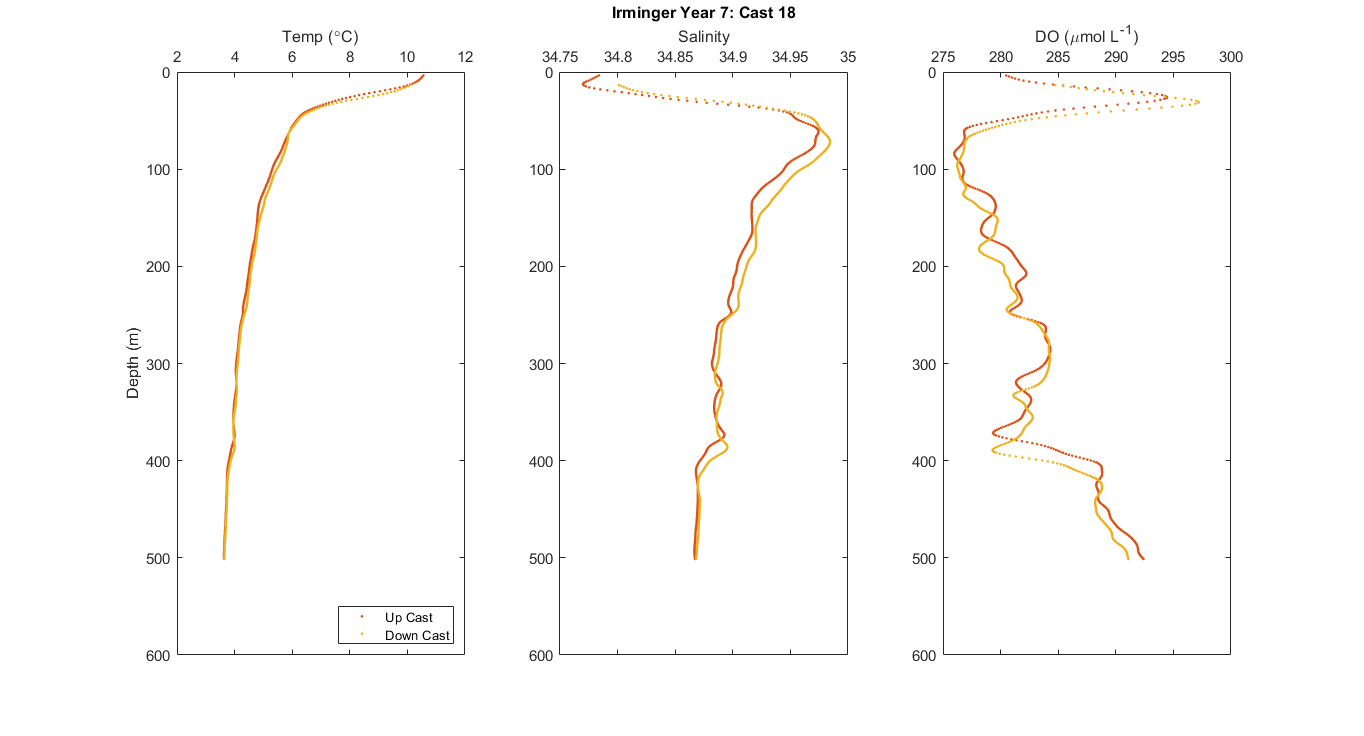


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46018up.t090C,ar46018up.depSM,'.','Color',red);
hold on
plot(ar46018down.t090C,ar46018down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46018up.sal00,ar46018up.depSM,'.','Color',red);
hold on
plot(ar46018down.sal00,ar46018down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 18')

s3 = subplot(1,3,3);
plot(ar46018up.sbeox0MLL*44.661,ar46018up.depSM,'.','Color',red);
hold on
plot(ar46018down.sbeox0MLL*44.661,ar46018down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

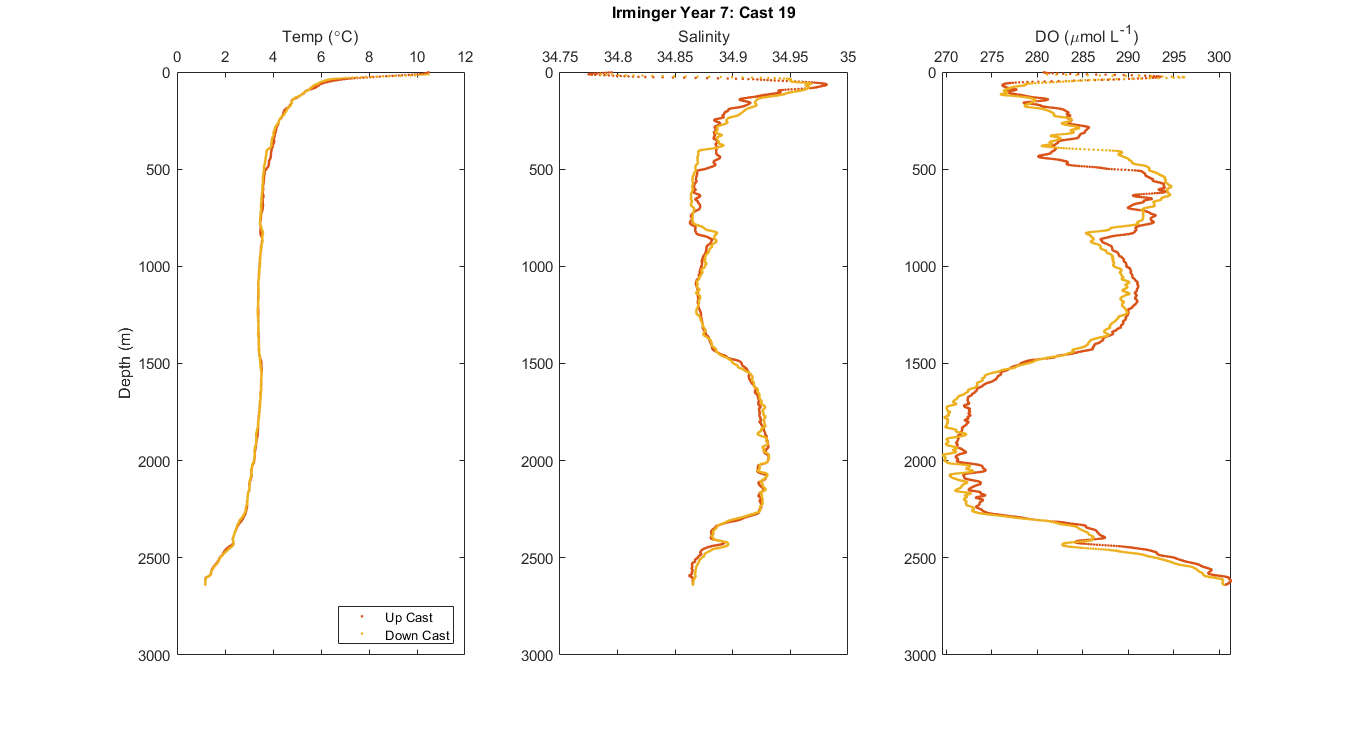


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar46019up.t090C,ar46019up.depSM,'.','Color',red);
hold on
plot(ar46019down.t090C,ar46019down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar46019up.sal00,ar46019up.depSM,'.','Color',red);
hold on
plot(ar46019down.sal00,ar46019down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 7: Cast 19')

s3 = subplot(1,3,3);
plot(ar46019up.sbeox0MLL*44.661,ar46019up.depSM,'.','Color',red);
hold on
plot(ar46019down.sbeox0MLL*44.661,ar46019down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')